clear; clc; close all;

split_percent = 10/11;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

Y_Train = categorical(Y_Train);
Y_Test = categorical(Y_Test);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [25×1000000 double]
      Labels: [7    9    1    8    7    6    3    9    1    8    7    6    1    9    5    1    2    5    7    2    9    4    1    7    5    7    9    5    6    5    8    8    7    5    4    1    4    4    8    7    2    1    5    6    4    9    …    ]


dsTest =   MyDataStore with properties:

    Features: [25×100000 double]
      Labels: [5    1    2    9    8    4    3    7    4    8    3    1    9    1    9    5    6    7    6    1    5    5    8    5    2    6    6    1    1    7    6    1    8    4    1    5    2    8    5    1    8    3    7    4    5    6    …    ]


#### SDN

layers = [
    featureInputLayer(2*N-1, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(N-1)
    softmaxLayer
    classificationLayer
    ]

layers =   12×1 Layer array with layers:

     1   ''   Feature Input           19 features
     2   ''   Fully Connected         150 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         150 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         150 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         150 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         9 fully connected layer
    11   ''   Softmax                 softmax
    12   ''   Classification Output   crossentropyex

#### SDN-II

layers = [
    featureInputLayer(M*M, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(N-1)
    softmaxLayer
    classificationLayer
    ]

layers =   12×1 Layer array with layers:

     1   ''   Feature Input           25 features
     2   ''   Fully Connected         150 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         150 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         150 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         150 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         9 fully connected layer
    11   ''   Softmax                 softmax
    12   ''   Classification Output   crossentropyex

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

#### SDN

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |        9.38% |       2.2065 |          0.0010 |
|       1 |          50 |       00:00:08 |       37.50% |       1.4721 |          0.0010 |
|       1 |         100 |       00:00:09 |       60.16% |       0.9397 |          0.0010 |
|       1 |         150 |       00:00:10 |       62.50% |       0.8213 |          0.0010 |
|       1 |         200 |       00:00:11 |       67.97% |       0.7113 |          0.0010 |
|       1 |         250 |       00:00:12 |       79.69% |       0.6062 |          0.0010 |
|       1 |         300 |       00:00:13 |       82.81% |       0.

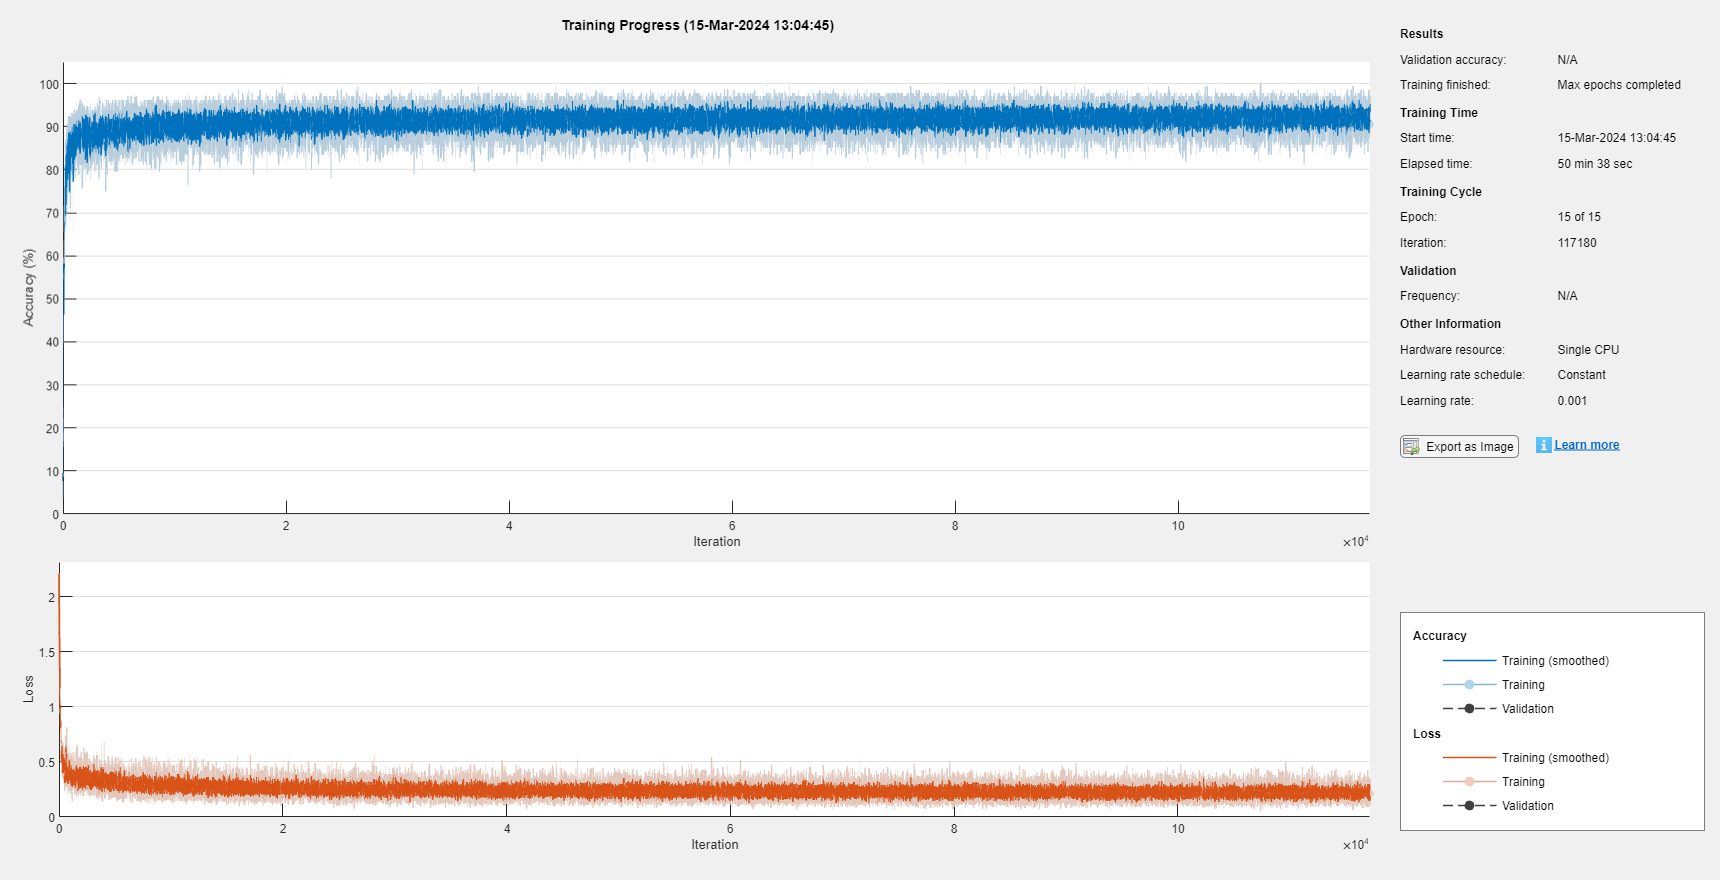

net =   SeriesNetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers, options)

#### SDN-II

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        9.38% |       2.2209 |          0.0010 |
|       1 |          50 |       00:00:03 |       39.84% |       1.5117 |          0.0010 |
|       1 |         100 |       00:00:04 |       53.91% |       1.2501 |          0.0010 |
|       1 |         150 |       00:00:04 |       57.03% |       0.9998 |          0.0010 |
|       1 |         200 |       00:00:05 |       72.66% |       0.7890 |          0.0010 |
|       1 |         250 |       00:00:06 |       79.69% |       0.6157 |          0.0010 |
|       1 |         300 |       00:00:07 |       68.75% |       0.

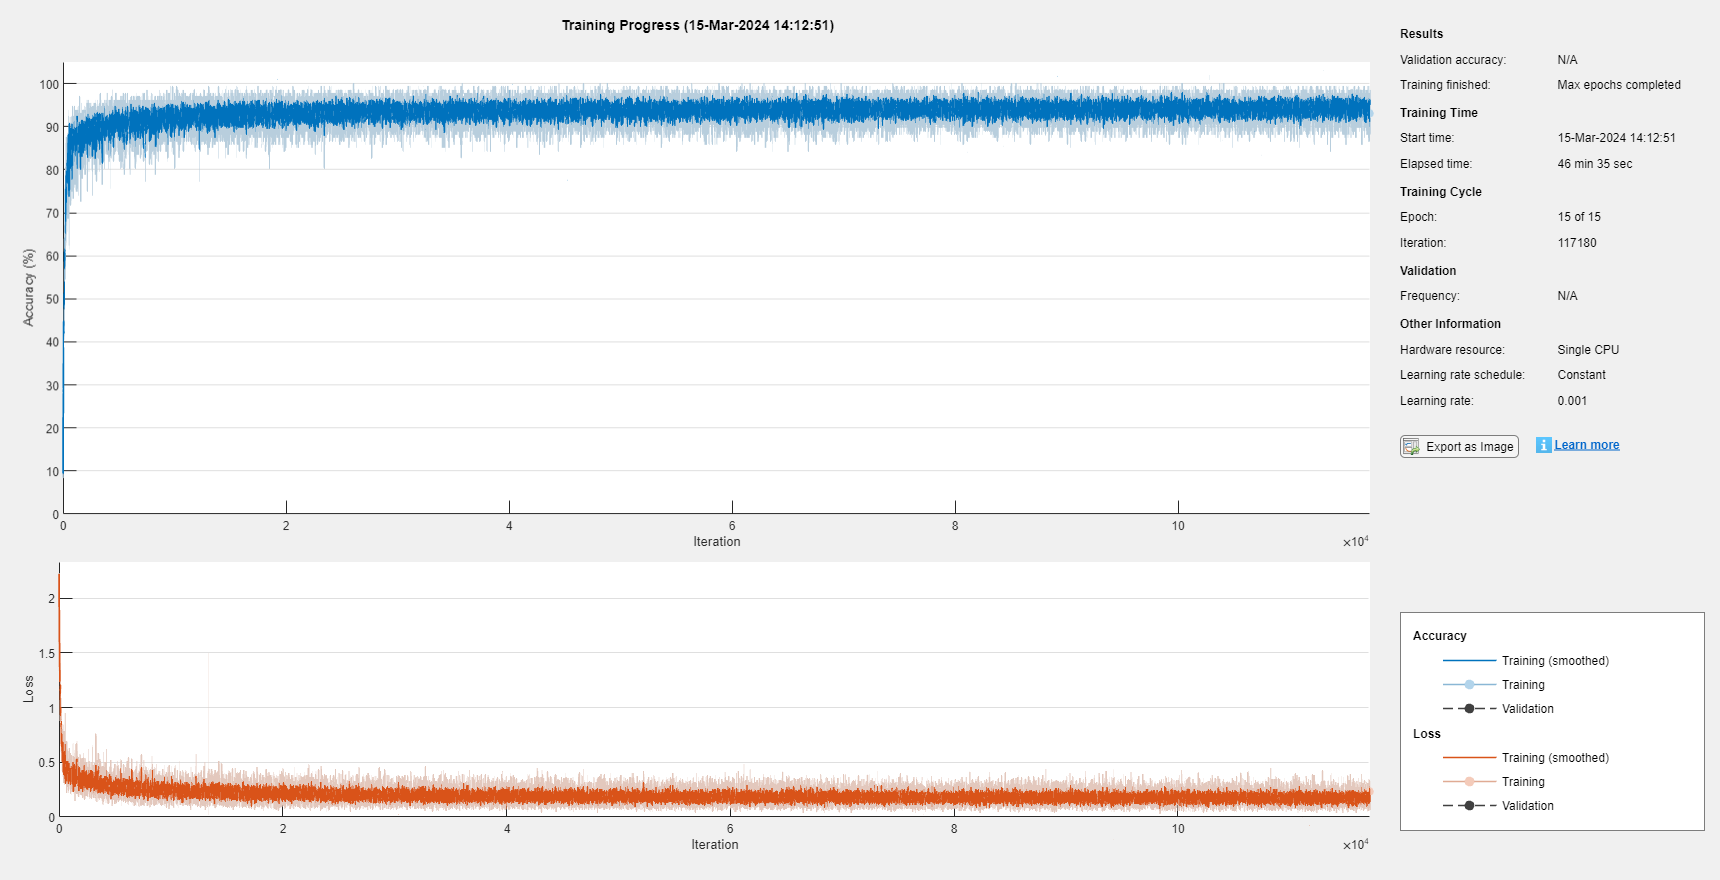

net =   SeriesNetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers, options)

# Testing

load SDN
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

#### SDN

YPred = classify(net, X_Test.');
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

accuracy = 0.9217

#### SDN-II

YPred = classify(net, X_Test.');
YValidation = dsTest.Labels.';
accuracy = sum(YPred==YValidation)/numel(YValidation)

accuracy = 0.9420

Test(DOA, net);

Estimated Number of Sources = 6
Actual Number of Sources = 6


Test2(DOA, net);

Estimated Number of Sources = 1
Actual Number of Sources = 1


function r = R2r(R)
M = size(R, 1);
r = zeros(M*M, 1);

re_R = real(R);
im_R = imag(R);

r(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        r(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end
end

function Test(DOA, net)
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
N = sensor_locations(M) + 1;
L = 200;        % # of snapshots
phi_min = 30;
phi_max = 150;
delta_phi = 1;  % angle resolution

K = randi(N-1);     % # of sources
doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);

doa = round(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 30 * rand;     % min = 0 dB, max = 30 dB
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;
R = (1 / L) * (y * y');

z = R(:);
z1 = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
z2 = z1(1:N-1);
r = [real(z2); z1(N); imag(z2)];

estimated_K = classify(net, r.');
estimated_K = double(estimated_K);

disp("Estimated Number of Sources = " + estimated_K);
disp("Actual Number of Sources = " + K);
end

function Test2(DOA, net)
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
N = sensor_locations(M) + 1;
L = 200;        % # of snapshots
phi_min = 30;
phi_max = 150;
delta_phi = 1;  % angle resolution

K = randi(N-1);     % # of sources
doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);

doa = round(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 30 * rand;     % min = 0 dB, max = 30 dB
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;
R = (1 / L) * (y * y');

r = R2r(R);

estimated_K = classify(net, r.');
estimated_K = double(estimated_K);

disp("Estimated Number of Sources = " + estimated_K);
disp("Actual Number of Sources = " + K);
end